#  Development of Discrete Time State Space Models

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction 

Digital control is a branch of control theory that uses digital computers to act as system controllers. Depending on the requirements, a digital control system can take the form of a microcontroller to an ASIC to a standard desktop computer. They offer many advantages over conventional analog computers. Franklin's 1958 text “Sampled-Data Control Systems” (co-authored by Franklin's dissertation advisor, John R. Ragazzini) introduced digital control to a discipline which had previously operated almost exclusively in the analog domain. This breakthrough allowed control systems to become much more precise and reliable. Ragazzini's notable students are Rudolf E. Kálmán (see Kalman filters), Eliahu Ibraham Jury (Developed theory of  Z-transform)

In the computer control systems, the process are analog but the controller is digital. To enable communication between an analog and digital device, the continuous time analog signals need to be sampled before they can be processed by a digital controller. Similarly the discrete-time output of the digital controller should be converted to a continuous-time signal so that it can be injected to the process. Such an approach results in a sampled data system. Digital controllers for such sampled data systems are often designed using discrete time process models. Instead of using continuous-time models, it is convenient to describe the analog process by its sampled version, which is obtained by discretizing the continuous-time process model to a discrete-time model. 

**Learning Objectives:**

- To develop computer control  relevant discrete time linear perturbation models starting from continuous time linear ODE models

-  To understand relationship between eigenvalues of discrete time and continuous time state transition matrices 

## Digital Control Preliminaries

Computer-based control systems are used in a wide range of applications, from industrial automation to robotics, and they rely on several core components to function effectively. It uses computers or microprocessors and software to manage and regulate the systems. It can be used to control simple devices like room heater and air-conditioner, or complex systems like autonomous cars, airplanes, thermal power plants and chemical processes. 

- Computer control uses software and feedback systems to change a system's response. 

- The system's response is changed to achieve a desired output or behavior. 

- The effectiveness of the system depends on the quality of the hardware, software, and input data. 

A continuous time model described using ODEs is not suitable for design of computer based controllers and need to be discretized. To integrate a computer based digital controller with an analog plant,  some intermediate interfaces are required. Figure 1 shows the elements of Computer Based Controller for a typical process. The inputs to a system or desired output variables associated with a system are continuous time signals, while the controller resides as an algorithm in a computer. Any digital computer works with only with numbers sequentially in time as each processing step requires a finite time. As a consequence, a digital computer cannot deal with continuous time signals.  Analog sensor transmitter systems, such as temperature, pressure or speed measuring devices, on the other hand, generate proportionate voltage or current signals continuously in time. Also, as a consequence of sequential processing of numbers, a digital computer can generate manipulated inputs only as a sequence of numbers. Actuators used to change manipulated inputs, such as control valves, on the other hand, require input signal continuously in time. Thus, to facilitate interactions between the computer software and the system outside, it is necessary to use the following interfacing hardware devices:

-  Analog to Digital (D/A) Converter: Converts continuous time signals into a sequence of numbers at time intervals decided by the control system designer (ref. Figure 2) 

- Digital to Analog (D/A) Converter: Converts a a sequence of numbers into a continuous time signal. The most frequently used D/A Converter is Zero Order Hold, i.e. it reconstructs a piece-wise constant signal from a sequence of numbers (ref. Figure 3)

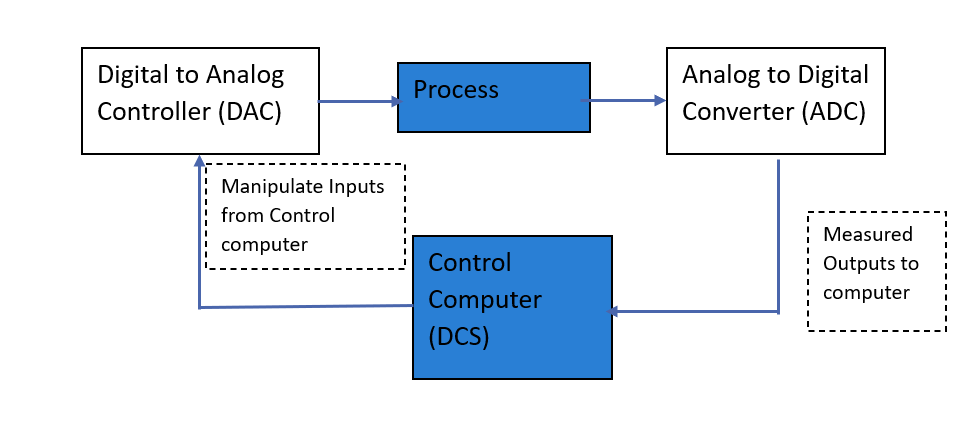

**Figure 1: Computer Based Controller**

**Simplifying Assumption 1: Measurement Sampling**

Continuous-time measurements such as temperature, pressure, velocity, etc from the analog process are sampled at uniform sampling interval of  $T$sec. Thus, measurements, $y(k)=y(t_k)$ are available in control computer only at time instant  $t_k=kT$ for $k=0,1,2,\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp$ Thus, inside a computer, measurements are just a sequence of values, as can be seen from Figure 2 shown below. 

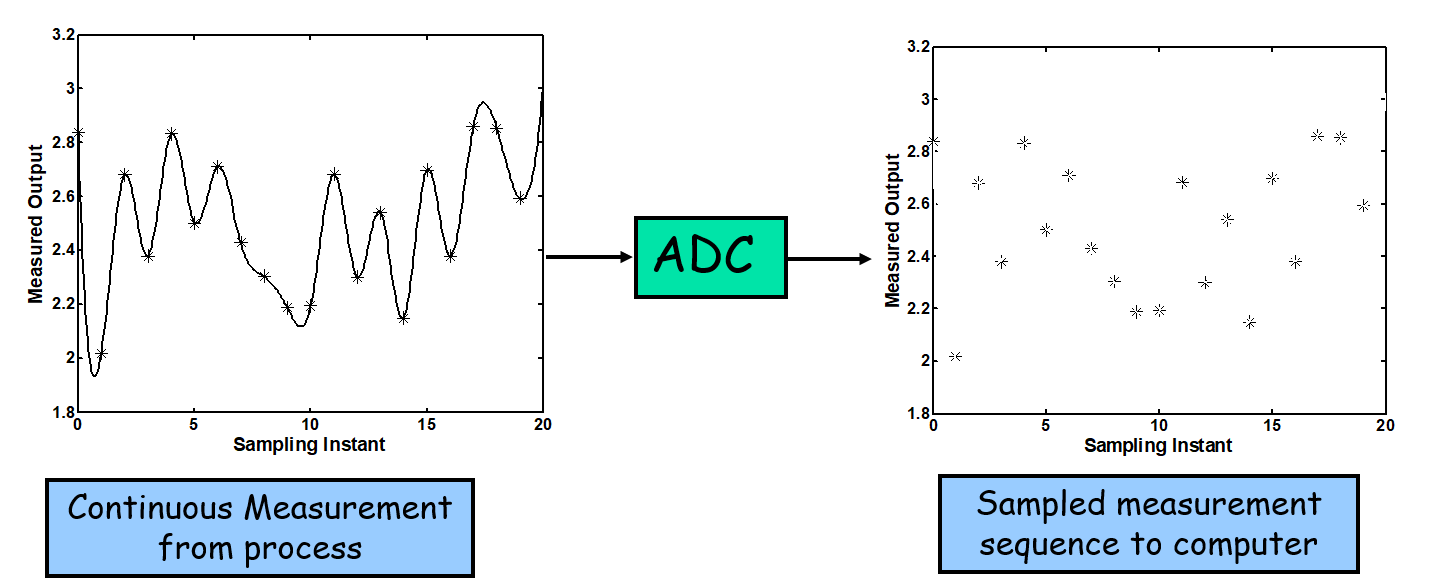

**Figure 2: Sampling of Measurement Signal**

There is a loss of data here. So, smaller the inter-sample time, more accurate is the signal representation. A key question faced by the user is to decide an appropriate value for the inter-sample time. Also, there is some finite time which is required to convert the signal to numbers, typically this time is in milliseconds or in microseconds. In our study, we are going to assume that Analog to Digital Converter ADC does this job instantaneously, that is, in zero time. This is a simplifying assumption for the ease of model development. 

Details of the hardware implementation of ADC and DAC are not needed for developing the mathematical framework for modeling and controller synthesis. The behavior of ADC and DAC is mathematically modelled as follows: 

- A/D  Converter: Measurements are sampled at a uniform sampling interval, say $T$ . Thus for a continuous time signal $\;y\left(t\right)\;\textrm{where}\;0\le t<\infty$ is available as a discrete time sequence of numbers $y\left(t_k \right)$ at time instant $t_k =k\;T\;\textrm{for}\;k=0,1,2,\ldotp \ldotp \ldotp \ldotp$

- D/A Converter (Zero Order Hold): The manipulated inputs are held constant during the interval between any two successive sampling instants, i.e. $\;u\left(t\right)=u\left(t_k \right)\;\textrm{for}\;k\;T\le t<\left(k+1\right)T$

Note that these are highly simplified models and implicitly assume that the time required for A/D conversion and D/A conversion are negligible w.r.t. the sampling interval $T$. 

**Simplifying Assumption 2: Constant Inputs Over Sampling Interval**

The digital controller will give outputs as a sequence of values or discrete-time values. However, when the output is to be given to the outside analog world, then it has to be converted to continuous form. Digital to Analog Converter  and a Zero Order Hold will do that job. Here we assume that the manipulated inputs from the control computer are held constant for one sampling instant. (Zero Order Hold). This is depicted in Figure 3.


$$u\left(t\right)=u\left(\textrm{kT}\right),\;\textrm{kT}<=t<=\left(k+1\right)T$$


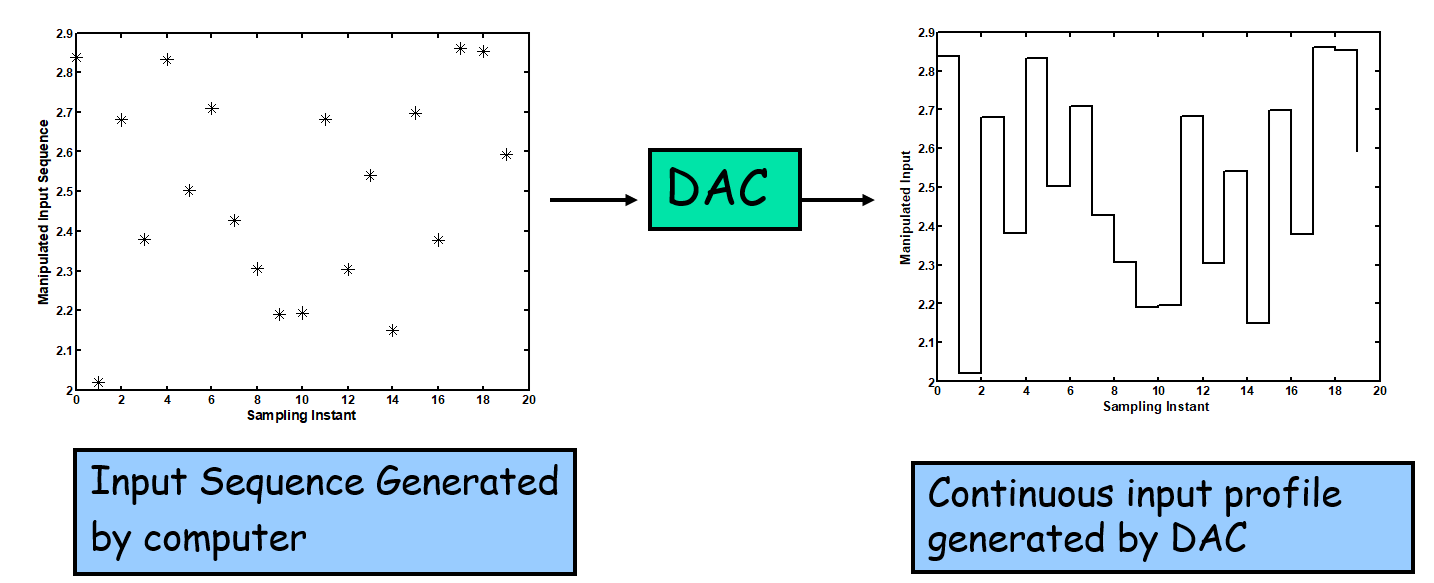

**Figure 3: Digital to Analog Conversion of Input Signal**

## Discrete-Time Representation of Continuous-Time Linear ODE Model

In a typical sampled data control system, data arrives or is sent out at uniformly sampled discrete time instants $\left(0,T,2T,3T,\ldotp \ldotp \ldotp \ldotp ,\textrm{kT},\ldotp \ldotp \ldotp \ldotp \right)$. Here $T$ is the sampling time chosen as per earlier guidelines given. Thus, we need a model that relates $x\left(k\;T\right)$ and / or $y\left(k\;T\right)$  with $u\left(k\;T\right)\;$ for $k=0,1,2\ldotp \ldotp \ldotp \ldotp \ldotp$despite of the fact that the continuous-time process dynamics are described by differential equations that relate the continuous signal $x\left(t\right)$ or $y\left(t\right)$ with input  $u\left(t\right)$. This is achieved by converting the differential equation in continuous-time to difference equation in discrete-time. In this session, we will learn how to do this and apply it to an example. We apply this discretization to the linear perturbation models developed in the previous lesson. Here you will notice that linearity is a great boon as we can construct the discrete time models using analytical solutions of the linear ODE model. 

Consider a linear dynamic state space model, developed at some operating point ([Linear Perturbation Model)](matlab:open('./L03_Local_Linear_Model_QTank_process.mlx')) as described in the previous lesson. We only consider the manipulated inputs at this stage and disturbance inputs will be treated later. 

$\frac{d\;x}{d\;t}=\textrm{Ax}\left(t\right)+{B\;}_u u\left(t\right)$   -----------(1a)

$y\left(t\right)=C\;x\left(t\right)$  ---------(1 b)

We are interested in simulating such a model starting from some initial condition, $x\left(0\right)$, when$\;u\left(t\right)$ is specified over $t\in \left\lbrack 0,t_f \right\rbrack$ under the following assumptions 

- Manipulated inputs are held piece-wise constant 

$u\left(t\right)=u\left(k\;T\right)$ for $t\in \left\lbrack k\;T,\left(k+1\right)T\right\rbrack$  for $k=0,1,2,\ldotp \ldotp \ldotp \ldotp ,N$------(2)

Thus, in computer controlled settings, we can develop a ***hopping solution ***that moves over intervals $t\in \left\lbrack k\;T,\left(k+1\right)T\right\rbrack$   for $k=0,1,2,\ldotp \ldotp \ldotp \ldotp ,N$ where $t_f =N\times T$ and $T$ represents the sampling interval. We introduce the following simplified notation, which will be used throughout the course 

$x\left(k\right)\equiv x\left(t=k\;T\right)$, $y\left(k\right)\equiv y\left(t=\textrm{kT}\right)$ and $u\left(k\right)\equiv u\left(t=k\;T\right)$  ------(3)

In discrete time settings, given the initial condition, $x\left(k\right)$ and input held constant over interval  $ t\in [kT,(k+1)T]$, i.e. $u\left(k\right)$, we want to find the solution of equation (1) so that we can predict the state of the sampled data system $x\left(k+1\right)$ at the next instant $\left(k+1\right)$. So the differential equation is integrated from $k\;T$ to $\left(k+1\right)T$ .

### Discrete-Time State Space Model   

Before we begin, let us consider a useful matrix operator, exponential of a matrix, which is defined as follows 

$e^{\textrm{At}} \equiv I+t\;A+\frac{1}{2!}t^2 \;A^2 +\ldotp \ldotp \ldotp \ldotp +\frac{1}{k!}t^k \;A^k +\ldotp \ldotp \ldotp \ldotp \ldotp$  ------(4)

Note that $e^{\textrm{At}}$ is a matrix and has some interesting properties, which can be proved easily 

$\frac{de^{\textrm{At}} }{\textrm{dt}}=A+\frac{2}{2!}t\;A^2 +\ldotp \ldotp \ldotp \ldotp +\frac{k}{k!}t^{k-1} \;A^k +\ldotp \ldotp \ldotp \ldotp \ldotp =Ae^{\textrm{At}}$  ------(5)

Also, 

$\int e^{\mathrm{At}} \;\mathrm{dt}\equiv t\times I+\frac{t^2 }{2}\;A+\frac{1}{2!}\frac{t^3 }{3}\;A^2 +\ldotp \ldotp \ldotp \ldotp +\frac{1}{k!}\frac{t^{k+1} }{k+1}\;A^k +\ldotp \ldotp \ldotp \ldotp$ ------(6)

and particularly when A is an invertible matrix 

$\int e^{\mathrm{At}} =\left(e^{\mathrm{At}} -I\right)A^{-1}$   ------(7)

Multiplying equation (1 a) by $e^{-A\;t}$ on both the sides

$e^{-A\;t} \frac{d\;x}{d\;t}=e^{-\mathrm{At}} \left\lbrack \mathrm{Ax}\left(t\right)+B_u \;u\left(t\right)\right\rbrack$    -------(8 a)

and rearranging the terms

$e^{-\mathrm{At}} \left\lbrack \frac{\mathrm{dx}}{\mathrm{dt}}-\mathrm{Ax}\left(t\right)\right\rbrack =\frac{d}{\mathrm{dt}}\left\lbrack e^{-A\;t} x\left(t\right)\right\rbrack =e^{-A\;t} B_u \;u\left(t\right)$  ----------(8b)

Now integrating the equation for one sampling interval from kT to (k+1)T

$\int_{\mathrm{kT}}^{\left(k+1\right)T} \left\lbrack e^{-\mathrm{At}} x\left(t\right)\right\rbrack \mathrm{dt}=\int_{\mathrm{kT}}^{\left(k+1\right)T} \left\lbrack e^{-\mathrm{At}} {\mathrm{B}}_u \;u\left(t\right)\right\rbrack \mathrm{dt}=\left\lbrack \int_{\mathrm{kT}}^{\left(k+1\right)T} e^A B_u \;\mathrm{dt}\right\rbrack u\left(\mathrm{kT}\right)\;\;\;$----------(9a)

Solving this integration

$e^{-A\left(k+1\right)T} x\left(k+1\right)=e^{-A\left(k\right)T} x\left(k\right)+\left\lbrack \int_{\mathrm{kT}}^{\left(k+1\right)T} e^{-\mathrm{At}} B_u d\tau \right\rbrack u\left(k\right)\;\;$-----------(9b)

Hence the solution of the discrete time difference equation is given as

$x\left(k+1\right)=e^{\mathrm{AT}} x\left(k\right)+\left\lbrack \int_0^T e^{A\tau } \;{\mathrm{B}}_u d\tau \right\rbrack u\left(k\right)$   -------(10)

This will give us a **linear discrete time model**.  Defining $\tau =\left(k+1\right)T-t$ we have $d\tau =-\textrm{dt}$ and

$x\left(k+1\right)=\left\lbrack e^{\textrm{AT}} \right\rbrack x\left(k\right)+\left\lbrack \int_0^T \exp \left(A\tau \right)\;B_u \;d\tau \right\rbrack u\left(k\right)$   --------(11) 

Computer Control Relevant Discrete Time Model is written as 

$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)\\
y\left(k\right)=\textrm{Cx}\left(k\right)
\end{array}$  ----------(12)

where

$\Phi =e^{\textrm{AT}} \;\;\textrm{and}\;\Gamma =\int_0^T \exp \left(A\tau \right)\;B_u \;d\tau$   ------(13) 

The above given model in equation (7) is a **Discrete-Time State Space Mode**l, which is a linear ** Difference Equation **discrete time. 

### Computation of  Discrete-Time Model Matrices 

When matrix A has linearly independent eigen-vectors and is diagonalizable, i.e.

$A=\psi \;\Lambda \;\psi^{-1}$    ------(14)

where matrix $\psi \;$ consists of eigen-vectors of A and matrix $\Lambda \;$is diagonal matrix with eigenvalues of A appearing on the diagonal, it is easy to show that 

$e^{\textrm{AT}} =\psi \;e^{\Lambda T} \;\psi^{-1}$    ------(15a)

where $e^{\Lambda T}$ is a diagonal matrix of the form

$\;e^{\Lambda T} =\left\lbrack \begin{array}{ccc}
e^{\lambda_1 T}  & \ldotp \ldotp \ldotp \ldotp  & 0\\
0 & \ldotp \ldotp \ldotp \ldotp  & 0\\
0 & \ldotp \ldotp \ldotp \ldotp  & e^{\lambda_n T} 
\end{array}\right\rbrack$   ------(15b)

Here, $\lambda_i :1,2,\ldotp \ldotp \ldotp \ldotp ,n$ represent eigenvalues of matrix A.  Further, we can write 

$\;\Gamma =\int_0^T \exp \left(A\tau \right)\;\textrm{Bd}\tau \;=\left(\int_0^T \psi \;e^{\Lambda \tau } \;\psi^{-1} d\tau \right){\mathrm{B}}_u$   ------(16)

If matrix A is invertible, then it can be shown that

$\int_0^T \exp \left(A\tau \right)\textrm{Bd}\tau =\left(\Phi -I\right)A^{-1}$$\Rightarrow$$\Gamma =\left(\Phi -I\right)A^{-1} B_u$ ------(17) 

There is an alternate way of computing the discrete time state space model and it's solution from the linear differential equation model. Consider the linear differential equation model(state space model) in continuous domain given by equation (1) with initial condition $x\left(t\right)$and $u\left(t\right)=u\left(k\right)$ over $k\;T\le t\le \left(k+1\right)T$. Taking Laplace transform of equation (1)

$\textrm{sx}\left(s\right)-x\left(k\right)=A\;x\left(s\right)+B_u u\left(s\right)$  -------(18)

So,

$\left\lbrack \textrm{sI}-A\right\rbrack x\left(s\right)-x\left(k\right)=B_u \;u\left(s\right)$  -----------(19)

$\left\lbrack \textrm{sI}-A\right\rbrack x\left(s\right)=x\left(k\right)+B_u u\left(s\right)$ ---------(20)

Let the input $u\left(k\right)$ be unit step function, so the Laplace transform $u\left(s\right)=\frac{1-e^{-\mathrm{Ts}} }{s}u\left(k\right)$, then equation (20) becomes

$\left\lbrack \textrm{sI}-A\right\rbrack x\left(s\right)=x\left(k\right)+\frac{1-e^{-\textrm{Ts}} }{s}B_u \;u\left(k\right)$-----------(21)

Taking Laplace inverse of equation (13), to obtain the solution $x\left(k\right)$

$x\left(s\right)={\left\lbrack \mathrm{sI}-A\right\rbrack }^{-1} \left\lbrack x\left(k\right)+\frac{1-e^{-\mathrm{Ts}} }{s}B\;u\left(k\right)\right\rbrack$----------(22)

Taking Laplace inverse of equation (13), to obtain the solution x(k) 

$x\left(k+1\right)=L^{-1} \left\lbrace {\left\lbrack \mathrm{sI}-A\right\rbrack }^{-1} \left\lbrack x\left(k\right)+\frac{1-e^{-\mathrm{Ts}} }{s}B_u \;u\left(k\right)\right\rbrack \right\rbrace$-----------(23)

Comparing equation (23) with equation (12) and (13), we get

${\Phi =e}^{\mathrm{AT}} =L^{-1} \left\lbrack {\left\lbrack \mathrm{sI}-A\right\rbrack }^{-1} \right\rbrack$   ----(24a)

 $\Gamma =\int_0^T \exp \left(A\tau \right)\textrm{Bd}\tau =L^{-1} \left\lbrack {\left\lbrack \textrm{sI}-A\right\rbrack }^{-1} \frac{1-e^{-\textrm{Ts}} }{s}B_u \right\rbrack$---------(24b)

#### Example: Discrete Time Model for DC motor (Astrom and Wittenmark, 1994)

Let us take an example of DC motor, the normalized continuous domain state space model and the derivation of corresponding discrete domain model is given.

Normalized State Space Model of an Electric DC Motor is given as 

$\begin{array}{l}
\frac{\mathrm{dx}}{\mathrm{dt}}=\left\lbrack \begin{array}{cc}
-1 & 0\\
1 & 0
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack u\\
y=\left\lbrack \begin{array}{cc}
0 & 1
\end{array}\right\rbrack x
\end{array}$    ------(25)

${\left(\mathrm{sI}-A\right)}^{-1} ={\left\lbrack \begin{array}{cc}
s+1 & 0\\
-1 & s
\end{array}\right\rbrack }^{-1} =\frac{1}{s\left(s+1\right)}\left\lbrack \begin{array}{cc}
s & 0\\
1 & s+1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{1}{s+1} & 0\\
\frac{1}{s\left(s+1\right)} & \frac{1}{s}
\end{array}\right\rbrack$   ------(26)

From equation (24a and 24b), 

$\Phi ={L^{-1} {\left\lbrack \mathrm{sI}-A\right\rbrack }^{-1} |_{t=T} =L}^{-1} \left\lbrace \left\lbrack \begin{array}{cc}
\frac{1}{s+1} & 0\\
\frac{1}{s\left(s+1\right)} & \frac{1}{s}
\end{array}\right\rbrack \right\rbrace \;=\left\lbrack \begin{array}{cc}
e^{-T}  & 0\\
1-e^{-T}  & 1
\end{array}\right\rbrack$        ------(27)

and 

 $\Gamma =\int_0^T e^{A\tau } Bd\tau =\int_0^T \left\lbrack \begin{array}{cc}
e^{-\tau }  & 0\\
1-e^{-\tau }  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack d\tau \;=\left\lbrack \begin{array}{c}
1-e^{-T} \\
T-1+e^T 
\end{array}\right\rbrack$   ------(28)

## **Solution of Difference Equation Model **

Starting from the initial condition $x\left(0\right)$ and recursively using equation (12), we can write 

$\begin{array}{l}
x\left(1\right)=\Phi x\left(0\right)+\Gamma u\left(0\right)\\
x\left(2\right)=\Phi x\left(1\right)+\Gamma u\left(1\right)=\Phi^2 x\left(0\right)+\Phi \Gamma u\left(0\right)+\Gamma u\left(1\right)\\
x\left(3\right)=\Phi x\left(2\right)+\Gamma u\left(2\right)=\Phi^3 x\left(0\right)+\Phi^2 \Gamma u\left(0\right)+\Phi \Gamma u\left(1\right)+\Gamma u\left(2\right)\\
\ldotp \ldotp \ldotp =\ldotp \ldotp \ldotp \ldotp \\
x\left(k\right)=\Phi x\left(k-1\right)+\Gamma u\left(k-1\right)=\Phi^k x\left(0\right)+\Phi^{k-1} \Gamma u\left(0\right)+\ldotp \ldotp \ldotp +\Phi \Gamma u\left(k-2\right)+\Gamma u\left(k-1\right)
\end{array}$  ------(29)

Thus, we can express the solution $x\left(k\right)\;\textrm{and}\;y\left(k\right)\;$ as 

$x\left(k\right)=\Phi^k x\left(0\right)+\sum_{j=0}^{k-1} \Phi^{k-1-j} \Gamma u\left(j\right)$    ------------(30)

$y\left(k\right)={C\Phi }^k x\left(0\right)+C\sum_{j=0}^{k-1} \Phi^{k-1-j} \Gamma u\left(j\right)$----------(31)

## Selection of Sampling Interval T

While converting the continuous linear models to discrete domain, the sampling time has to be judiciously selected, so that the closed-loop performance of the process after discretization does not deviate much from the original continuous model. Selecting sampling time T is one of the critical issues, it requires domain knowledge to make a good choice of sampling time. 

- **"Too long” T:** impossible to reconstruct the original signal

- **“Too short” T:** increases load on computer and on data storage: 

- For example for systems like furnace, it takes 30 to 40 minutes for any change to fully manifest in the output. Hence, it is meaningless to sample data at every second (T = 1 second). Such data will not have important information and it will only add to the storage. On the other hand for systems like fuel cells, the sampling time required would be in milliseconds due to the fast dynamics of the process. 

Choice of sampling period, "Too Long or Too Short" strongly depends on the system and signal characteristics. The **Shannon’s Sampling Theorem **provides an upper bound on the choice of sampling interval. The sampling theorem specifies **the minimum-sampling rate **at which a continuous-time signal needs to be **uniformly sampled **so that the highest frequency content of the original signal can be recovered or reconstructed by these samples alone. 

**Shannon Sampling Theorem: **If a continuous time signal contains no frequency components higher than $\omega^*$ Hz, then it can be completely determined by uniform samples taken at a sampling rate $f_s$ samples per second where

$\frac{1}{T}=f_s \ge 2\omega^*$ i.e. $T\le \frac{1}{2\omega^* }$

Thus, the sampling frequency should be at least twice the highest frequency of interest of the process dynamics. The minimum sampling frequency, $f_N =2\omega^*$, is called as the Nyquist frequency. What is "frequency of interest" comes from domain knowledge and varies from process to process.  Figure 4 demonstrates **Shannon's Sampling Theorem. **

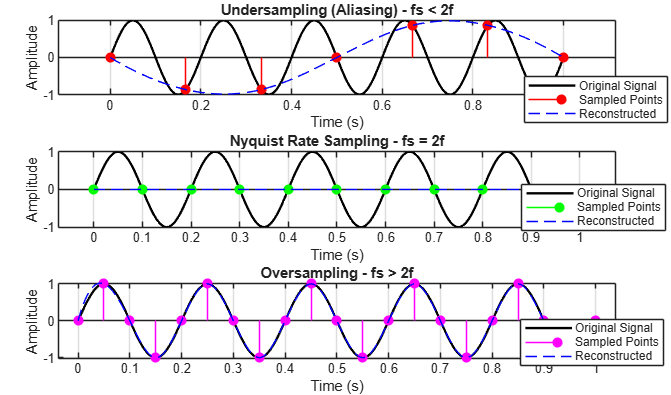

**Figure 4: Demonstration of Shannon's Sampling Theorem**

We can see that there is a loss of information, when the signal is under-sampled. A sine-wave with a frequency of 5 Hz is sampled at 6 Hz, 10 Hz and 20 Hz. It is observed that when the 5 Hz sinusoid is sampled at a rate of 6 Hz, which is less than the Nyquist frequency of 10 Hz, then there is a loss of information in the sampled sine-wave (for example, the frequency of the signal is not recovered). On the other hand, when sampled using the Nyquist frequency of 10 Hz, the frequency of the sine-wave is recovered but not the amplitude. Choosing a higher frequency of sampling equal to the Nyquist frequency recovers both, the amplitude as well as the frequency of the sine-wave. 

### Practical Guideline for Selecting Sampling Time T from Time Response of Dynamical Systems

Guidelines are available in the literature for selection of the sampling period, which are based on dominant time constant, rise time, settling time etc. (see Astrom and Wittenmark (1999) for details). Let   $T_R$ denote **′rise time′ **of the system, that is the time required by the system to reach the final value for the first time, when a step input is given.  Then the No. of samples per rise time $N_r=T_R/T$.  It is reasonable to choose $N_r$ between 4 to 10. 

- For first order systems, **Rise time = Time Constant **

- For second order systems with natural frequency  $\omega _0 $ and damping coefficient ζ

$T_r =\frac{e^{\frac{\phi }{\tan \phi }} }{\omega_0 }$           where$\phi =\cos^{-1} \left(\zeta \right)$ 

Select sampling time T such that


$$\frac{T_r }{10}\le T\le \frac{T_r }{4}$$


As an illustration, consider a series RLC circuit as shown below in Figure 5, with the transfer function as shown. We will now see how to calculate the rise time from the transfer function 

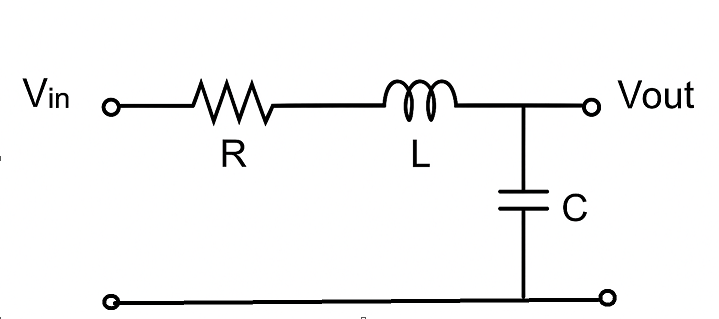

**Figure 5: RLC Series Circuit**

Let the Laplace transfer function model for the above circuit be expressed as follows 

  
$$G\left(s\right)=\frac{\frac{1}{\textrm{LC}}}{s^2 +s\frac{R}{L}+\frac{1}{\textrm{LC}}}=\frac{\omega_0^2 }{s^2 +2\varsigma \omega_0 s+\omega_0^2 }=\frac{0\ldotp 25}{s^2 +0\ldotp 75s+0\ldotp 25}$$


Rise Time can be calculated for the above circuit as per formula given above.

**Task 1:** Set the values of variables R, L and C. 


R=1.5;
L=2;
C=2;

**Task 2:** Create a transfer function variable G as per the equation, using R, L and C variables.

G = tf([0 1/(L*C)],[1 R/L 1/(L*C)]);

**Task 3: **Create variables w0 and zeta and assign the values 0.5 and 0.75 respectively.

w0=0.5;
zeta=0.75;

**Task 3: Create a variable phi and **Compute it's value using the formula$\phi =\cos^{-1} \left(\zeta \right)$

phi=acos(zeta);


ans =
 
  A = 
             x1        x2        x3        x4
   x1  -0.01547         0   0.03996         0
   x2         0  -0.01035         0   0.02769
   x3         0         0  -0.03996         0
   x4         0         0         0  -0.02769
 
  B = 
            u1       u2       u3
   x1  0.08325        0        0
   x2        0  0.06281        0
   x3        0  0.04786  0.01429
   x4  0.03122        0  0.01875
 
  C = 
        x1   x2   x3   x4
   y1  0.5    0    0    0
   y2    0  0.5    0    0
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
 
Continuous-time state-space model.


**Task 4: **Create a variable **Tr** and use the formula to calculate the rise time. Leave the equation without a semicolon, so that you can see the value.

Tr=(exp(phi/tan(phi)))/w0


Gs =
 
  From input 1 to output...
         0.04163
   1:  -----------
       s + 0.01547
 
                0.0004322
   2:  ---------------------------
       s^2 + 0.03804 s + 0.0002865
 
  From input 2 to output...
                0.0009561
   1:  ---------------------------
       s^2 + 0.05543 s + 0.0006183
 
         0.03141
   2:  -----------
       s + 0.01035
 
  From input 3 to output...
                0.0002854
   1:  ---------------------------
       s^2 + 0.05543 s + 0.0006183
 
                0.0002596
   2:  ---------------------------
       s^2 + 0.03804 s + 0.0002865
 
Continuous-time transfer function.


Note this value. 

**Task 5:**Select Sampling time such that there are 4 to 10 samples in one rise time. It means that the sampling time should be such that $\frac{4\ldotp 5387}{10}\le T\le \frac{4\ldotp 5387}{4}$. 

Select a proper sampling time $T$ in the dropdown menu. 

T=5;

We will write simple code to see the step response of the continuous time system and check the rise time.  Observe the step response. 

fprintf('\n\t Step Response of Linear Continuous and Discrete System  \t') ;
figure(1)
step(G)

phy =     0.8836         0    0.2565         0
         0    0.9206         0    0.1904
         0         0    0.7264         0
         0         0         0    0.8013


## Discrete-Time Dynamic Model for Q Tank Process

We have already obtained a [Continuous-time linear dynamical model for Q Tank](matlab:open('./L02_Linearization_of_noninear_Models.mlx')). We now analyze it further to obtain a discrete-time model. We will also compare the step responses of both the models. To observe the outputs learners can press the **Run** button. But one is advised to follow step wise procedure to understand the process of obtaining discrete-time models. 

% Modified Quadruple Tank System  

n_st = 4

gam =     0.6264    0.0529
    0.0250    0.4823
         0    0.3277
    0.2240         0


 
clear all;
close all;

### Loading Continuous Time Domain Model

Let us load Continuous Domain Linear Dynamical Model obtained in the previous session. These models are saved as **QTank_MinPhase_Model** and **QTank_NonMinPhase_Model**. To get the discrete-time models at different operating points, we need to specify the operating condition. 

**Task 1: **Specify Operating Condition, Minimum Phase or Non-minimum Phase. Let us select Minimum Phase first.

operating_pt=1;


cmod =
 
  A = 
             x1        x2        x3        x4
   x1  -0.01547         0   0.03996         0
   x2         0  -0.01035         0   0.02769
   x3         0         0  -0.03996         0
   x4         0         0         0  -0.02769
 
  B = 
            u1       u2
   x1  0.08325        0
   x2        0  0.06281
   x3        0  0.04786
   x4  0.03122        0
 
  C = 
        x1   x2   x3   x4
   y1  0.5    0    0    0
   y2    0  0.5    0    0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



if ( operating_pt == 1 )                        % Minimum phase system


	 Discrete Time Linear Perturbation Model at Given Steady State 	

    load QTank_MinPhase_Model QTank


dmod =
 
  A = 
           x1      x2      x3      x4
   x1  0.8836       0  0.2565       0
   x2       0  0.9206       0  0.1904
   x3       0       0  0.7264       0
   x4       0       0       0  0.8013
 
  B = 
            u1       u2
   x1   0.6264   0.0529
   x2  0.02502   0.4823
   x3        0   0.3277
   x4    0.224        0
 
  C = 
        x1   x2   x3   x4
   y1  0.5    0    0    0
   y2    0  0.5    0    0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Sample time: 8 seconds
Discrete-time state-space model.


elseif ( operating_pt == 2 )                    % Non-Minimum phase system 
    load QTank_NonMinPhase_Model QTank
end

**Task 2: **Observe the workspace variable QTank.cmod for linear continuous time state space model. It has 2 manipulated inputs and a disturbance input.

QTank.cmod


dmod =
 
  A = 
           x1      x2      x3      x4
   x1  0.8836       0  0.2565       0
   x2       0  0.9206       0  0.1904
   x3       0       0  0.7264       0
   x4       0       0       0  0.8013
 
  B = 
            u1       u2       u3
   x1   0.6264   0.0529  0.01579
   x2  0.02502   0.4823  0.01503
   x3        0   0.3277  0.09782
   x4    0.224        0   0.1345
 
  C = 
        x1   x2   x3   x4
   y1  0.5    0    0    0
   y2    0  0.5    0    0
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
 
Sample time: 8 seconds
Discrete-time state-space model.


**Task 3:** The  loaded model is a continuous-time linear state variable model at a specific operating point. As seen earlier the[ transfer function model ](matlab:open('./L02_Linearization_of_noninear_Models.mlx'))in s-domain can be obtained from it.  Convert the linear dynamical model **QTank.cmod** to Transfer Function Model **Gs **using the command **tf. **

Gs= tf( QTank.cmod  )  %%%TransferFunction model in continuous domain

Eig_A =    -0.0155
   -0.0103
   -0.0400
   -0.0277


### Sampling Time Selection

For generating the discrete time model, we need to select the sampling time. We have seen earlier how to select the sampling time.

To select sampling time for this process, we check the rise time $T_r$ as discussed earlier. For example, the transfer function model at **Minimum Phase Operating Point** w. r.t. the two inputs is obtained is shown below. 

$G\left(s\right)=\left\lbrack \begin{array}{cc}
\frac{2\ldotp 6}{1+62s} & \frac{1\ldotp 5}{\left(1+23s\right)\left(\left(1+62s\right)\right)}\\
\frac{1\ldotp 4}{\left(1+30s\right)\left(\left(1+90s\right)\right)} & \frac{2\ldotp 8}{1+90s}
\end{array}\right\rbrack$  ------(32)

The two second order transfer functions are approximated as first order with time delay models as follows

$g_{12} \left(s\right)=\frac{1\ldotp 5}{\left(1+23s\right)\left(\left(1+62s\right)\right)}\approx \frac{1\ldotp 5e^{-11\ldotp 5s} }{\left(1+73\ldotp 5s\right)}$  ------(33a)

$g_{21} \left(s\right)=\frac{1\ldotp 4}{\left(1+30s\right)\left(\left(1+90s\right)\right)}\approx \frac{1\ldotp 4e^{-15s} }{\left(1+105s\right)}$  ------(33b)

Among the 4 transfer functions, **fastest time constant is 62** and is used as a basis for selecting sampling time interval. Hence according to the guidelines for selecting sampling time, the sampling time should be selected such that


$$\frac{62}{10}\le T\le \frac{62}{4}$$
  

for faithful reconstruction of sampled signals.

### Generation of Discrete-Time Models

Now we generate discrete time linear perturbation model from the continuous model **cmod** using Matlab command c2d. [Continuous To Discrete](https://www.mathworks.com/help/control/ref/lti.c2d.html). Function c2d discretizes the continuous-time [dynamic system model](https://www.mathworks.com/help/control/ug/dynamic-system-models.html) **cmod** using zero-order hold on the inputs and a sample time of **samp_T** seconds.

**Task 4:** Select a suitable sampling time by following the guidelines for Selection of Sampling Time. As seen above any sampling time between, 6 to 15 is reasonable for the Q Tank Process. 

samp_T=8;

Eig_phy =     0.8836
    0.9206
    0.7264
    0.8013


QTank.samp_T = samp_T ;

phy_spectral_radius = 0.9206

phy = expm(samp_T * QTank.A_mat )    % Note: You need to use "expm" command and NOT exp command 

ans =     0.8836         0         0         0
         0    0.9206         0         0
         0         0    0.7264         0
         0         0         0    0.8013


n_st = length( QTank.A_mat ) 
gam = (phy - eye(n_st)) * inv(QTank.A_mat ) * QTank.B_mat(:,1:2) 
[nx, n_ip] = size(gam) ; 
[n_op, nx] = size( QTank.C_mat ) ;

% Alternatively, we can use Control Systems Toolbox Function c2d 

Continuous time state space model can also be obtained from the matrices QTank.A_mat, QTank.B_mat(:,1:2), QTank.C_mat, zeros(n_op, n_ip) using MATLAB [**ss**](https://in.mathworks.com/help/control/ref/ss.html) command. This model is without the disturbance input.

cmod = ss( QTank.A_mat, QTank.B_mat(:,1:2), QTank.C_mat, zeros(n_op, n_ip) )

**Task 5**:  Generate a discrete time linear model, **dmod using command c2d, omitting** the semicolon so that model can be seen in the results window.

fprintf('\n\t Discrete Time Linear Perturbation Model at Given Steady State \t') ;
dmod = c2d( cmod, samp_T )  % Continuous to discrete conversion state space model

## Discrete Time Model with Disturbance Signal 

In practice, very often a system is subject to measured or unmeasured  disturbance input, $d\left(t\right)$. From a system description viewpoint, the disturbance is another input in addition to the control input $u\left(t\right)$. From a user-viewpoint, both $d\left(t\right)$ and $u\left(t\right)$ affect the system dynamics, but the user can manipulate only $u\left(t\right)$. The disturbance$\;d\left(t\right)$ may be measured and thus known or unmeasured and thus unknown. Consider Continuous Time Linear Perturbation Model with control input u(t) and disturbance input $d\left(t\right)$that we developed in the previous lesson 

$\frac{d\;x}{d\;t}=A\;x\left(t\right)+B_u \;u\left(t\right)+B_d d\left(t\right)$  ---------(34)

In computer controlled systems, only the user-manipulated inputs are held piece-wise constant. However, disturbances $d\left(t\right)$ are NOT piecewise constant. To address this issue we use an assumption. 

**Simplifying Assumption: **Sampling interval ($T$) is small enough so that the disturbance inputs can be approximated as piecewise constant functions during the sampling interval.

$d\left(t\right)=d\left(k\right)$ for $t=\textrm{kT}\le t<\left(k+1\right)T$     ------(35)

Under the above Simplifying Assumption,  **Computer Control  Relevant Discrete Time Linear Perturbation Models** can be developed as follows:

$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_d d\left(k\right)\\
y\left(k\right)=C\;x\left(k\right)
\end{array}$--------------(36)

where

$\Phi =e^{\textrm{AT}}$ ,  $\Gamma =\int_0^T e^{A\tau } B_u d\tau$ $\Gamma_d =\int_0^T e^{A\tau } B_d d\tau$   ------(37)

Note that, as far as real disturbance signal is concerned, equation (36) is an approximate model and generates realistic results only when the sampling interval is sufficiently small. 

**Task 6**: Now generate a discrete time linear mode with disturbance, **dmod_d using command c2d and from the model QTank.cmod**

dmod = c2d( QTank.cmod, samp_T )  % Continuous to discrete conversion state space model

## Eigenvalues of Continuous and Discrete Time Linear Systems 

Recall that the dynamics of a Continuous time Linear System are given by equation (1)  and a discrete time model of the form (12) derived by defining $\Phi =e^{\textrm{AT}} \;\;\textrm{and}\;\Gamma =\int_0^T \exp \left(A\tau \right)\textrm{Bd}\tau$. What is the relationship between stability characteristics of the continuous time model and discrete time model? Taking Laplace transform of (14) and rearranging, we can write 

    $x\left(s\right)={\left(\textrm{sI}-A\right)}^{-1} \left\lbrace x\left(0\right)+\textrm{Bu}\left(s\right)\right\rbrace =\frac{1}{\det \left(\textrm{sI}-A\right)}$$\textrm{adj}\left(\textrm{sI}-A\right)\left\lbrace x\left(0\right)+\textrm{Bu}\left(s\right)\right\rbrace$   ------(38)

From (15), it is clear that the unforced response, i.e. when $u\left(t\right)=0\;\textrm{for}\;t\ge 0$, is governed by roots of the denominator polynomial, i.e. $\det \left(\textrm{sI}-A\right)=0$, i.e. eigenvalues of matrix A. To simplify the analysis, let us assume that A is diagonalizable.  Thus, we can write $A=\Psi \Lambda \Psi^{-1}$.  We consider different cases of dynamical systems 

**Case 1: **Matrix $A$ has distinct eigenvalues and linearly independent eigen-vectors 

$A=\Psi \Omega \Psi^{-1} \Rightarrow \Phi =e^{\textrm{AT}} =\Psi \left\lbrack e^{\Omega T} \right\rbrack \Psi^{-1}$------(39)

 where $\Omega$ is a diagonal matrix with eigenvalues of $A$, i.e. $\lambda_i :i=1,2,\ldotp \ldotp \ldotp ,n\;$, appearing as the diagonal elements and columns of $\Psi$ are eigen-vectors of $A$. Note that Matrix$A$ and Matrix $\Phi$ (equation 1) have identical eigen-vectors. Also, if $\lambda$ is eigenvalue of  $A$ then  $e^{\lambda T}$ is eigenvalue of $\Phi$.  Let 

$\lambda_i =a_i +jb_i$  -------(40) 

represent an eigenvalue of  $A$.  Then

$\eta_i =e^{\lambda_i T} =e^{\left(a_i +jb_i \right)T} =e^{a_i T} \left\lbrack \cos \left(b_i T\right)+j\;\sin \;\left(b_i T\right)\right\rbrack$------(41) 

is eigenvalue of $\Phi$. Note that $\left|\left\lbrack \cos \left(\beta_i T\right)+j\;\sin \;\left(\beta_i T\right)\right\rbrack \right|=1$. This implies that the location of $\eta_i =e^{\lambda_i T}$ in z-plane is determined by $e^{a_i T}$  (where $z\equiv e^s$) 

$\textrm{If}\;a_i <0\Rightarrow e^{a_i T} <1$------(42)

Thus, an eigenvalue $\eta_i$, corresponding to a **stable mode** in the continuous domain maps to a stable mode in the discrete domain and  $\eta_i =e^{\lambda_i T}$ lies** inside the unit circle in the z-plane.**

$a_i =0\Rightarrow \lambda_i =e^{\eta_i T} =\left\lbrack \cos \left(b_i T\right)+j\;\sin \;\left(b_i T\right)\right\rbrack$  ---- (43)

**lies ON the unit circle in z plane and **

$a_i >0\Rightarrow e^{a_i T} >1$------(44)

Thus, an eigenvalue $\lambda_i$, corresponding to an** unstable mode** in the continuous domain maps to an unstable mode in the discrete domain and  $\lambda_i =e^{\eta_i T}$ lies **outside the unit circle in the z-plane.**

**Case 2:** Matrix $A$ has some repeated eigenvalues. 

In general, for any matrix $A$, there is a non-singular matrix $\Psi$ such that 

$\Psi^{-1} A\Psi =J=\textrm{block}\;\textrm{daigonal}\left\lbrack \begin{array}{ccccc}
J_1  & J_2  & \ldotp \ldotp  & \ldotp \ldotp  & J_r 
\end{array}\right\rbrack$-------(45)

where $J_i$ is Jordan block associated with eigenvalue $\lambda_i$ of A. Jordan block of order 1 takes the form $J_i =\lambda_i$  while for order $m_i >1$takes the form 

$J_i ={\left\lbrack \begin{array}{ccccc}
\lambda_i  & 1 & 0 & \ldotp \ldotp  & 0\\
0 & \lambda_i  & 1 & \ldotp \ldotp  & 0\\
\ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp \\
0 & 0 & \ldotp \ldotp  & \ldotp \ldotp  & 1\\
0 & \ldotp \ldotp  & \ldotp \ldotp  & \ldotp \ldotp  & \lambda_i 
\end{array}\right\rbrack }_{m_i \times m_i }$----(46)

$e^{\textrm{At}} =\Psi \left\lbrack e^{J_t } \right\rbrack \Psi^{-1} =\Psi \left\lbrack \sum_{i=1}^r \sum_{k=1}^{m_i } e^{\eta_i T} R_{i,k} \right\rbrack \Psi^{-1}$-------(47)

**Note: **If for every eigenvalue of a matrix, the geometric  multiplicity equals the algebraic multiplicity, then it is diagonalizable.

The process of discretization does not alter the stability of a linear system as will be discussed in ***Lesson 2 of Module 4***. Figure 2 shows conformal map $z=\exp \left(\textrm{sT}\right)$ 

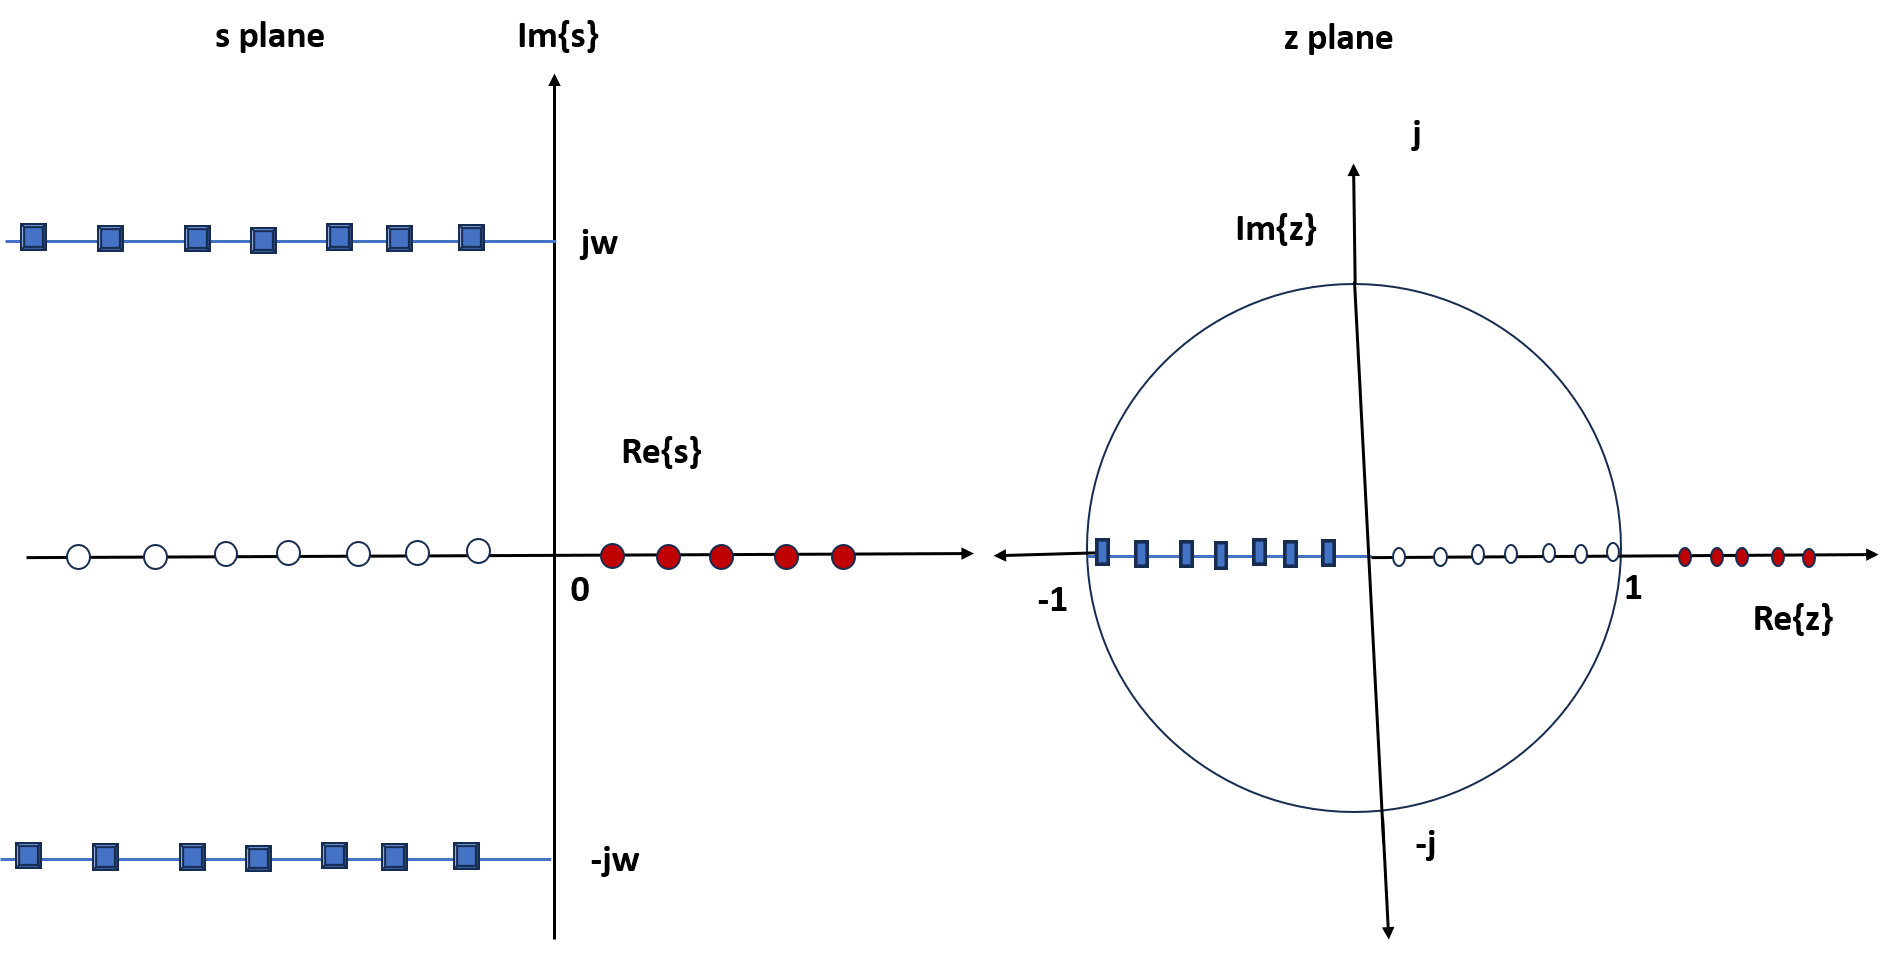

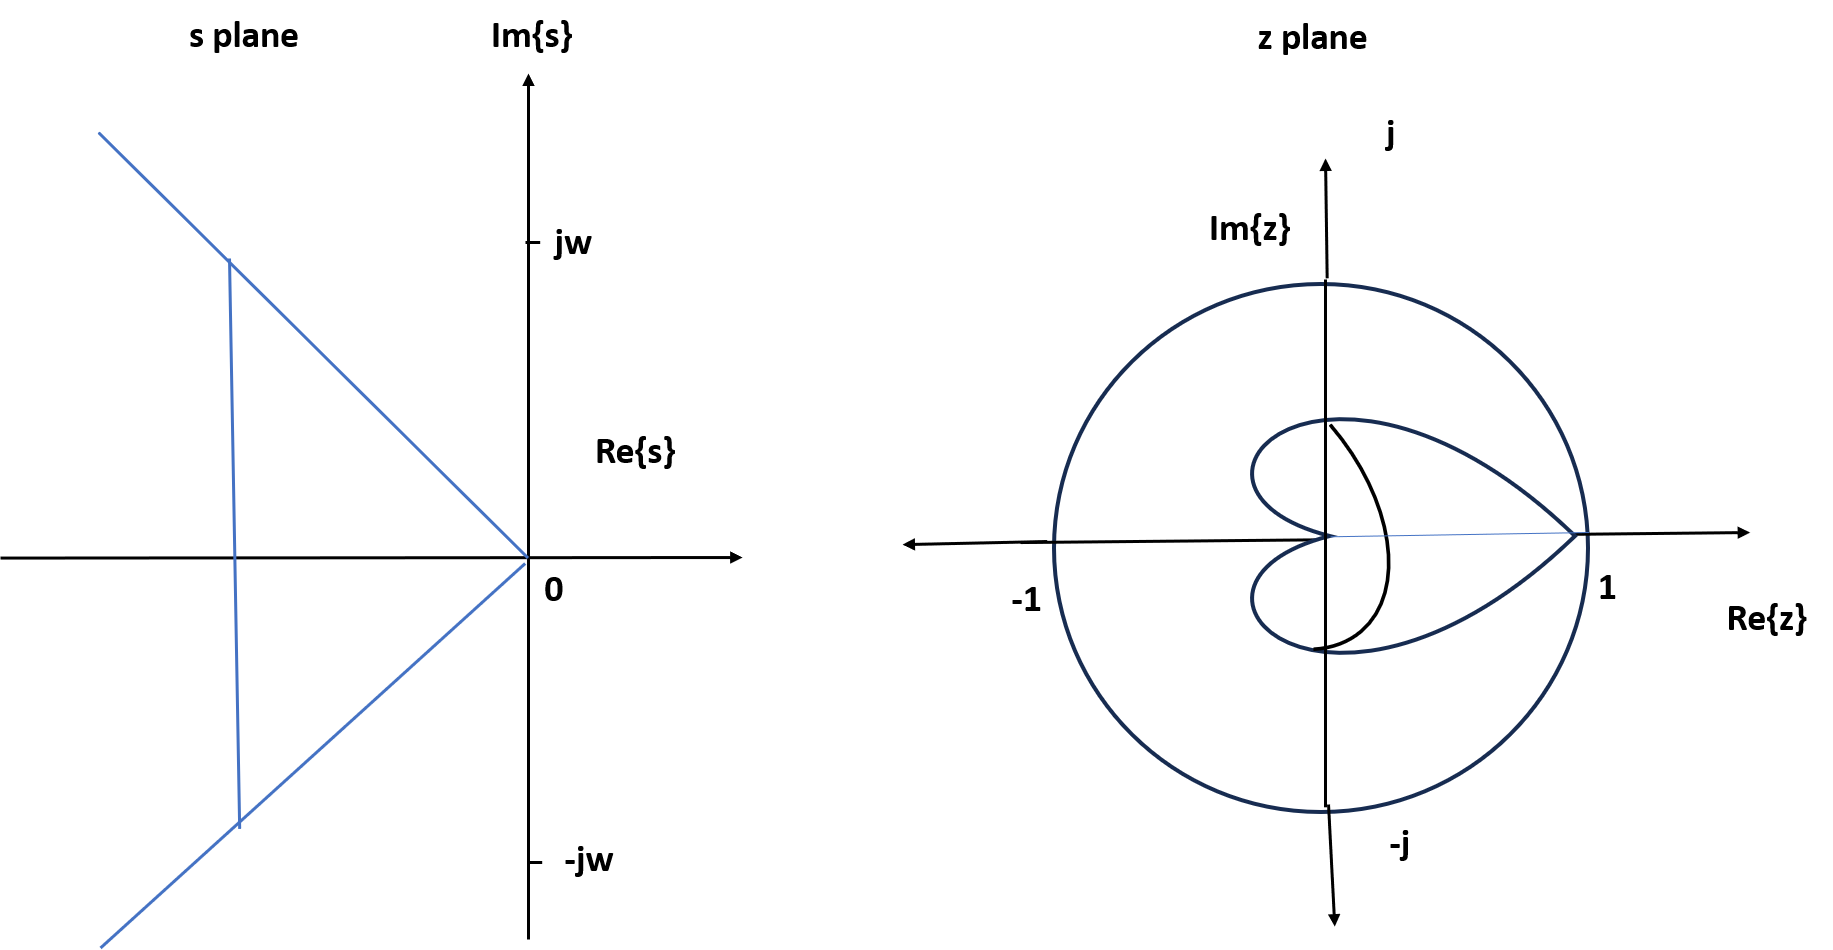

**Figure 6: Stability Regions in s-plane and z-plane**

The stability properties of continuous-time systems depend on the locations of the poles in the Laplace s-plane. The stability boundary is the jω-axis. When the poles lie in the open left half of the plane the system is stable. Similarly, the stability properties of **discrete-time systems** depend on the locations of the **poles in the z-plane**. The stability boundary is the unit circle, with poles inside the unit circle being stable, as shown below. 

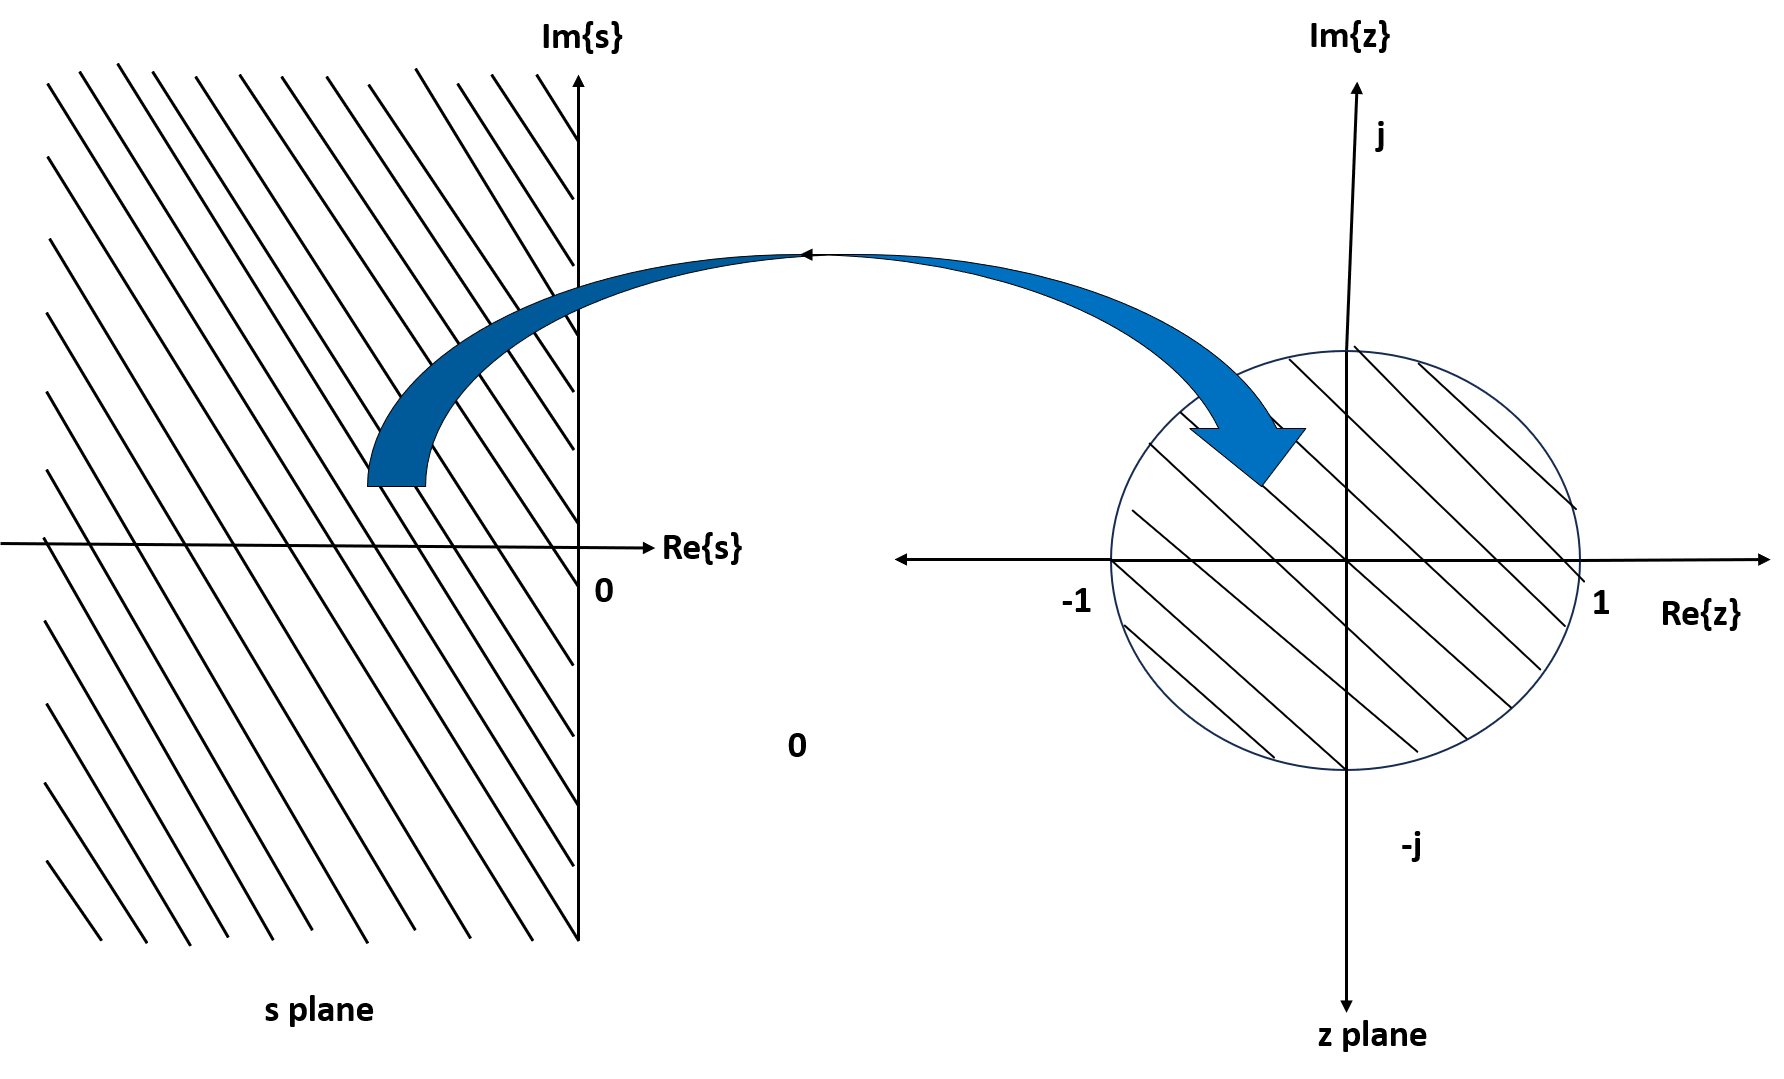

**Figure 7: s plane-z plane mapping**

% Find eigenvalues of continuous time model for QTank
Eig_A = eig(QTank.A_mat) 

% Find eigenvalues of continuous time model for QTank
Eig_phy = eig(phy) 
phy_spectral_radius = max(abs(Eig_phy))   % Find spectral radius of phy matrix 

% Crosscheck

expm(diag(samp_T*Eig_A))

## Conclusion

In this lesson,  we have developed computer control relevant linear discrete time difference equation model starting from a linear continuous ODE model models. We have also studied relationship between the eigenvalues of the state transition matrix in the continuous time and in discrete time. We noticed that s**table region in s-plane: Left Half plane ** maps to **Stable region in z-plane: Unit Circle**

- All poles (eigenvalues) in the left half of s-plane map inside the unit circle around the origin in z-plane. 

- All poles (eigenvalues) on the imaginary axis in s-plane map on the boundary of the unit circle in z-plane

- All poles (eigenvalues) in the right half of s-plane map outside the unit circle around the origin in z-plane. 

Thus the asymptotic dynamic behavior of a discrete linear model is completely determined by the eigenvalues of the state transition matrix and discretization does not alter stability of a linear dynamic model. ***Lesson 2 of Module 4 presents details of the derivation in support of this statement. ***

## References

Astrom, K. J., and B. Wittenmark, Computer Controlled Systems, Prentice Hall India (1994).

Franklin, G. F., Powell, J. D., and M. L. Workman, Digital Control Systems, Addison Wesley, 1990. 

Johansson, K. H. (2000). The Quadruple-Tank Process: A multivariable laboratory process with an adjustable zero, IEEE Trans. on Control Systems Technology, 8(3), 456-465.

Goodwin, G. C., Graebe, S. F.  and M. E. Salgado, Control Systems Design, Prentice Hall India, 2003. 